# Experiment with LSTMCNNpathToEEG model(3 channels)

## Load data

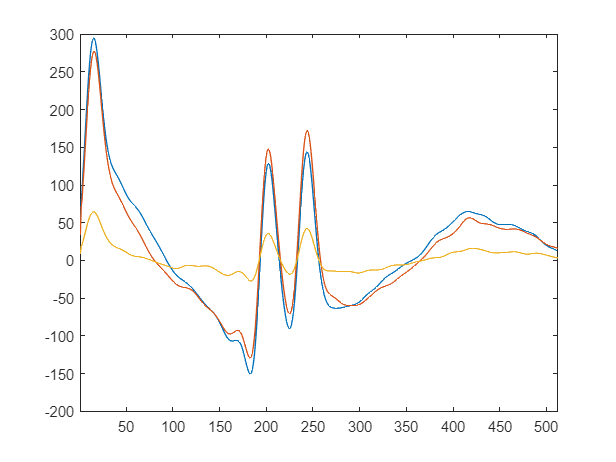

XTrain = load(fullfile('DataSet','HyperparameterSearch','Train','XSearchTrain.mat')).XSearchTrain;
YTrain = load(fullfile('DataSet','HyperparameterSearch','Train','YSearchTrain.mat')).YSearchTrain;

XTest = load(fullfile('DataSet','HyperparameterSearch','Test','XSearchTest.mat')).XSearchTest;
YTest = load(fullfile('DataSet','HyperparameterSearch','Test','YSearchTest.mat')).YSearchTest;

trainDs = {XTrain, YTrain};
testDs = {XTest, YTest};

figure;i = 1;
plot(XTrain{i}');
xlim([1 size(XTrain{i},2)]);

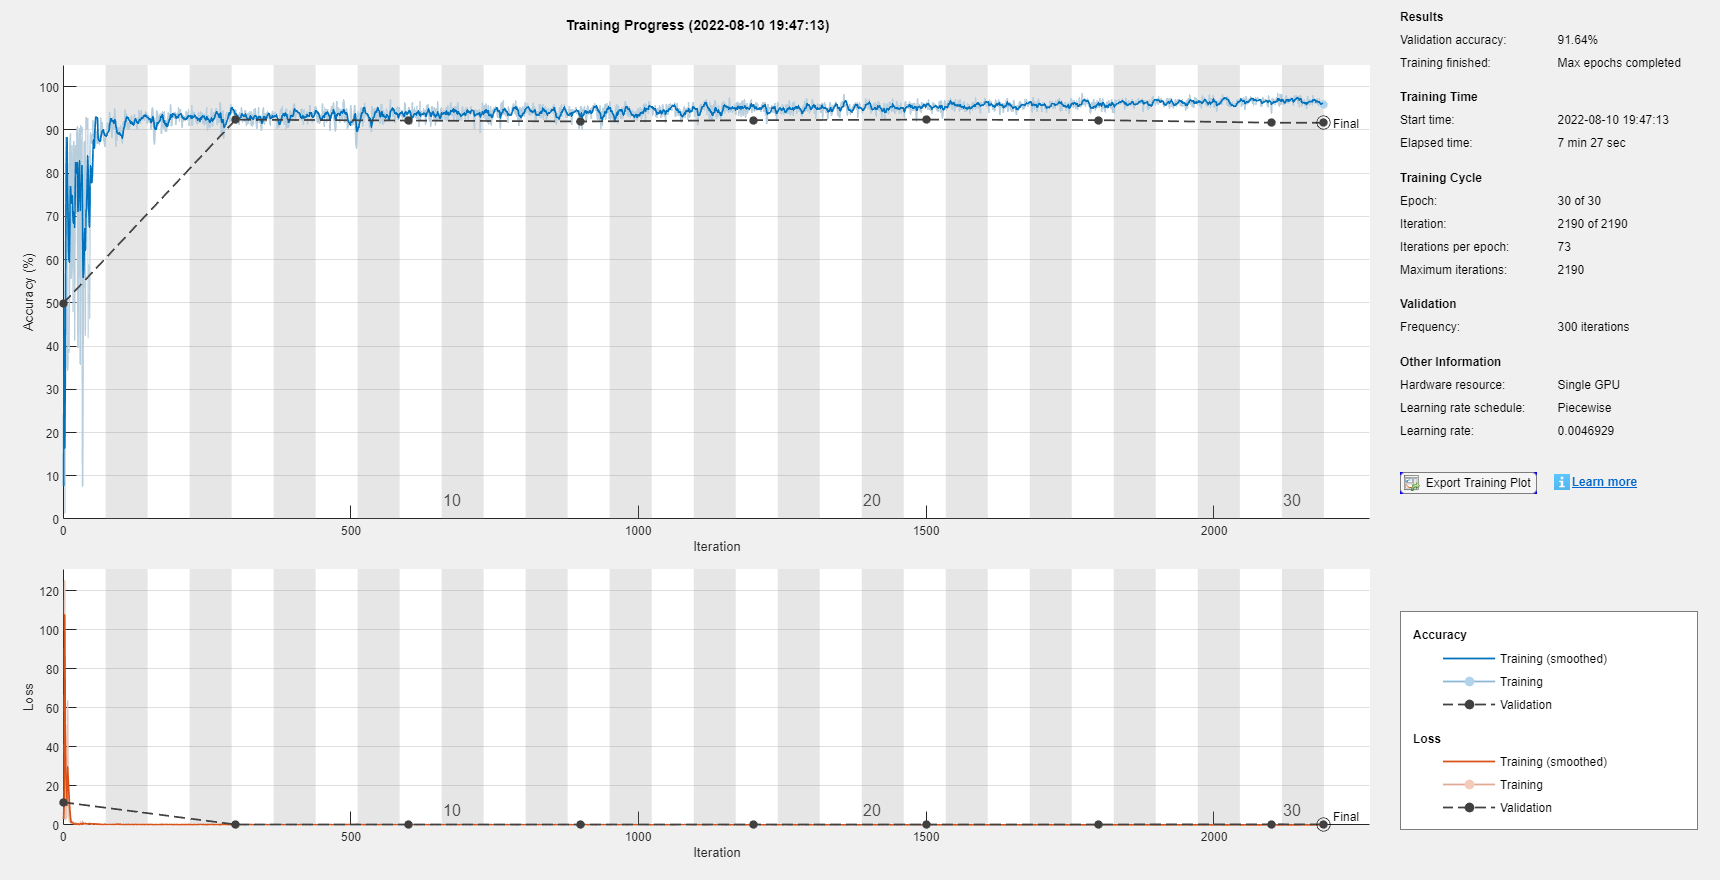

rng(1);
miniBatchSize = 63;
learningrate = 0.019776;
numFeatures = size(XTrain{1},1);
numLSTMBlocks = 4;
numHiddenUnits = 23;
numCNNBlocks = 4;
filterSize = 17;
numFilters = 6;
numResponse = numel(categories(YTest{1}));
layers = constructLSTMCNN(numFeatures,numLSTMBlocks,numHiddenUnits, ...
                numCNNBlocks,filterSize,numFilters,numResponse,true); 

options = trainingOptions('adam', ...
    'MaxEpochs',30, ...
    'MiniBatchSize',miniBatchSize, ...
    'InitialLearnRate',learningrate, ...
    'LearnRateDropPeriod',10, ...
    'LearnRateDropFactor',0.75, ...
    'LearnRateSchedule','piecewise', ...
    'Plots','training-progress',...
    'GradientThreshold',1, ...
    'shuffle','every-epoch',...
    'Verbose',0,...
    'DispatchInBackground',true, ...
    'ValidationData',testDs, ...
    'ValidationFrequency',300);


LSTMCNNnet = trainNetwork(XTrain,YTrain,layers,options);

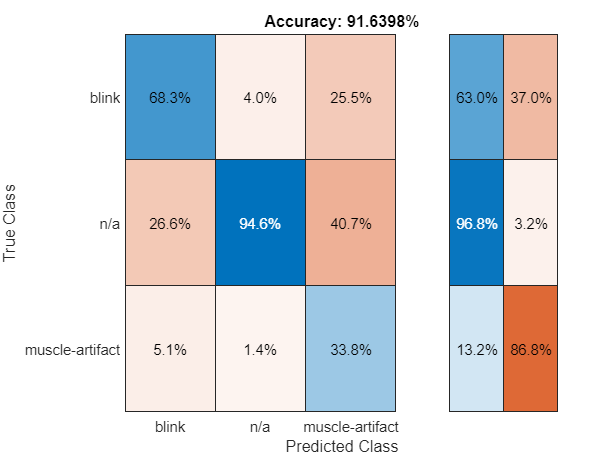

YPred = classify(LSTMCNNnet, XTest, "MiniBatchSize",miniBatchSize);

%%%%%%%%%%%%%%%%%
valError = 0;
for k = 1:length(YPred)
    % fix this
    valError = valError + mean(YPred{k} == YTest{k});
end
% return a numeric scalar
valError = 1 - valError/length(YPred);

TY = [];
Y = [];
YTest = YTest.';
for k = 1:numel(testDs{1})
    TY = [TY;YTest{k}];
    Y = [Y;YPred{k}];
end
percentageAccuracy=(1-valError)*100;
figure;

confusionchart(TY(:),Y(:),'Normalization','column-normalized','Title',['Accuracy: ' num2str(percentageAccuracy) '%'], ...
   'RowSummary','row-normalized');